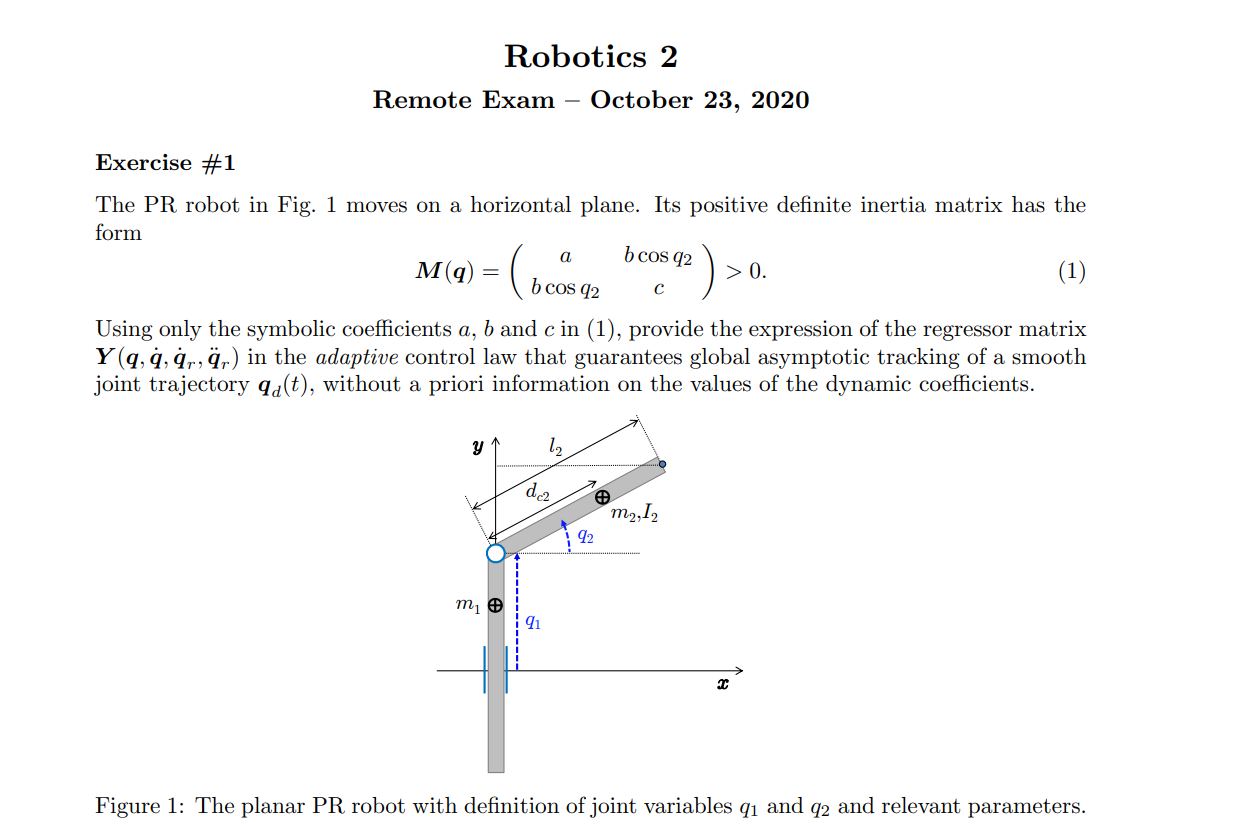

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,1];
R2Robot=['pr';'yx';sigmaD]

R2Robot = 3×2 char array
    'pr'
    'yx'
    ' '


n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
       

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
       


[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
       

si falla aquí está el error


$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} 0 & -l_{2}\,\sin\left(q_{2}\left(t\right)\right)\\ 1 & l_{2}\,\cos\left(q_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{cc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & {\dot{q}}_{2} \end{array}\right)$$

$$T = \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: [1×1 sym]
    Ti: [1×2 sym]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: [1×1 sym]
                     Ti: [1×2 sym]
                      M: [2×2 sym]


Pc

$$Pc = \left(\begin{array}{cc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

M

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

Trans.PTotal

$$ans = \left(\begin{array}{c} l_{2}\,\cos\left(q_{2}\right)\\ q_{1}+l_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

jacobian(Trans.PTotal(2),z.q)

$$ans = \left(\begin{array}{cc} 1 & l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$cac = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

Csubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$S = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

cac

$$cac = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

S

$$S = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

[Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...
MSubs second iteration (before re-replacement)
si falla uncomment this line verify  una lineas arriba


$$Msubs = \left(\begin{array}{cc} a_{2} & a_{3}\,\cos\left(q_{2}\right)\\ a_{3}\,\cos\left(q_{2}\right) & a_{1} \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3} \end{array}\right)$$

% %[m1*dc1^2 + m2*dc2^2 + m3*dc3^2 + I1 + I2 + I3; m3*dc3^2 + I3; m2 + m3; dc3*m3; 2*dc2*m2]


% known_params=[z.m(3),z.dc(3),z.I(3)]'%z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'
% known_params=sym([])
% [Msubs2, dynamicParameters2, aM2]=adaptative_control_get_paramateres2(M,dynamicParameters,aM,known_params,[])

 
known_params =
 
[ empty sym ]
 



% [struct_sub_mat,params]=Adpatative_Control_parameters(Msubs,dynamicParameters,known_params,aM)

[All, dynamicParamsReturn, aM]= getDynamicParameters2([M,S],q,[z.q_dot],1)

$$submats = \left(\begin{array}{cc} a_{2} & a_{3}\,\cos\left(q_{2}\right)\\ a_{3}\,\cos\left(q_{2}\right) & a_{1} \end{array}\right)$$

 
a_k_sym =
 
[ empty sym ]
 

a_k_sym_zeros =

     []


B_u =

     []


I_u =

     []



$$new\_a = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$partial\_a = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$partial\_a = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$a\_u\_sym = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

a_u_sym_zeros =      0
     0
     0


B =     13
     7
     6


I =      1
     2
     3


$$new\_a2 = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

B_a =      4
     4
     4


I_a =      1
     2
     3


struct_sub_mat = struct with fields:
    new_submats: [2×2 sym]


params = struct with fields:
    known_parameters_: [0×0 sym]


params = struct with fields:
    known_parameters_: [0×0 sym]
     known_parameters: [0×0 sym]


params = struct with fields:
      known_parameters_: [0×0 sym]
       known_parameters: [0×0 sym]
    unknown_parameters_: [3×1 sym]


params = struct with fields:
      known_parameters_: [0×0 sym]
       known_parameters: [0×0 sym]
    unknown_parameters_: [3×1 sym]


params = struct with fields:
      known_parameters_: [0×0 sym]
       known_parameters: [0×0 sym]
    unknown_parameters_: [3×1 sym]
     unknown_parameters: [3×1 sym]


struct_sub_mat = struct with fields:
      new_submats: [2×2 sym]
    new_submats_u: [2×2 sym]


struct_sub_mat = struct with fields:
      new_submats: [2×2 sym]
    new_submats_u: [2×2 sym]
    new_submats_k: [2×2 sym]


struct_sub_mat = struct with fields:
       new_submats: [2×2 sym]
     new_submats_u: [2×2 sym]
     new_submats_k: [2×2 sym]
    new_submats_u_: [2×2 sym]


struct_sub_mat = struct with fields:
       new_submats: [2×2 sym]
     new_submats_u: [2×2 sym]
     new_submats_k: [2×2 sym]
    new_submats_u_: [2×2 sym]
    new_submats_k_: [2×2 sym]


struct_sub_mat = struct with fields:
       new_submats: [2×2 sym]
     new_submats_u: [2×2 sym]
     new_submats_k: [2×2 sym]
    new_submats_u_: [2×2 sym]
    new_submats_k_: [2×2 sym]


params = struct with fields:
      known_parameters_: [0×0 sym]
       known_parameters: [0×0 sym]
    unknown_parameters_: [3×1 sym]
     unknown_parameters: [3×1 sym]


## Computing adaptative parameters

% known_params=[z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'
known_params=sym([]);

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...
MSubs second iteration (before re-replacement)
si falla uncomment this line verify  una lineas arriba


$$All = \left(\begin{array}{cccc} a_{2} & a_{3}\,\cos\left(q_{2}\right) & 0 & -a_{3}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ a_{3}\,\cos\left(q_{2}\right) & a_{1} & 0 & 0 \end{array}\right)$$

$$dynamicParamsReturn = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3} \end{array}\right)$$

[struct_sub_mat,params]=Adpatative_Control_parameters(All,dynamicParamsReturn,known_params,aM)

struct_sub_mat.new_submats_u
struct_sub_mat.new_submats_k

$$submats = \left(\begin{array}{cccc} a_{2} & a_{3}\,\cos\left(q_{2}\right) & 0 & -a_{3}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ a_{3}\,\cos\left(q_{2}\right) & a_{1} & 0 & 0 \end{array}\right)$$

 
a_k_sym =
 
[ empty sym ]
 

a_k_sym_zeros =

     []


B_u =

     []


I_u =

     []



$$new\_a = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$partial\_a = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$partial\_a = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$a\_u\_sym = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

a_u_sym_zeros =      0
     0
     0


B =     13
     7
     6


I =      1
     2
     3


$$new\_a2 = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

B_a =      4
     4
     4


I_a =      1
     2
     3


struct_sub_mat = struct with fields:
    new_submats: [2×4 sym]


params = struct with fields:
    known_parameters_: [0×0 sym]


params = struct with fields:
    known_parameters_: [0×0 sym]
     known_parameters: [0×0 sym]


params = struct with fields:
      known_parameters_: [0×0 sym]
       known_parameters: [0×0 sym]
    unknown_parameters_: [3×1 sym]


params = struct with fields:
      known_parameters_: [0×0 sym]
       known_parameters: [0×0 sym]
    unknown_parameters_: [3×1 sym]


params = struct with fields:
      known_parameters_: [0×0 sym]
       known_parameters: [0×0 sym]
    unknown_parameters_: [3×1 sym]
     unknown_parameters: [3×1 sym]


struct_sub_mat = struct with fields:
      new_submats: [2×4 sym]
    new_submats_u: [2×4 sym]


struct_sub_mat = struct with fields:
      new_submats: [2×4 sym]
    new_submats_u: [2×4 sym]
    new_submats_k: [2×4 sym]


struct_sub_mat = struct with fields:
       new_submats: [2×4 sym]
     new_submats_u: [2×4 sym]
     new_submats_k: [2×4 sym]
    new_submats_u_: [2×4 sym]


struct_sub_mat = struct with fields:
       new_submats: [2×4 sym]
     new_submats_u: [2×4 sym]
     new_submats_k: [2×4 sym]
    new_submats_u_: [2×4 sym]
    new_submats_k_: [2×4 sym]


struct_sub_mat = struct with fields:
       new_submats: [2×4 sym]
     new_submats_u: [2×4 sym]
     new_submats_k: [2×4 sym]
    new_submats_u_: [2×4 sym]
    new_submats_k_: [2×4 sym]


params = struct with fields:
      known_parameters_: [0×0 sym]
       known_parameters: [0×0 sym]
    unknown_parameters_: [3×1 sym]
     unknown_parameters: [3×1 sym]


params.known_parameters
params.known_parameters_

$$ans = \left(\begin{array}{cccc} a_{\mathrm{u2}} & a_{\mathrm{u3}}\,\cos\left(q_{2}\right) & 0 & -a_{\mathrm{u3}}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ a_{\mathrm{u3}}\,\cos\left(q_{2}\right) & a_{\mathrm{u1}} & 0 & 0 \end{array}\right)$$

params.unknown_parameters

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

params.unknown_parameters_

 
ans =
 
[ empty sym ]
 


## linear paramatrization for unkown terms

% % %complete model

 
ans =
 
[ empty sym ]
 


a_order_u = params.unknown_parameters

$$ans = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

Msubs_u = struct_sub_mat.new_submats_u(:,1:n)

$$ans = \left(\begin{array}{c} m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ m_{1}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

Ssubs_u = struct_sub_mat.new_submats_u(:,n+1:2*n)
% gSubs = diag(All(:,7:9))
% FSubs = All(:,10:12)

torqueSubs_u = Msubs_u*q_ddot + Ssubs_u*z.q_dot %+ gSubs +FSubs*qd

$$a\_order\_u = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

[Y_u, Yshort_u]=getLinearParametrization(torqueSubs_u,a_order_u)

$$Msubs\_u = \left(\begin{array}{cc} a_{\mathrm{u2}} & a_{\mathrm{u3}}\,\cos\left(q_{2}\right)\\ a_{\mathrm{u3}}\,\cos\left(q_{2}\right) & a_{\mathrm{u1}} \end{array}\right)$$

Y_u

$$Ssubs\_u = \left(\begin{array}{cc} 0 & -a_{\mathrm{u3}}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

## linear paramatrization for kown terms

% % %complete model
a_order_k = params.known_parameters([1,2,3])

$$torqueSubs\_u = \left(\begin{array}{c} -a_{\mathrm{u3}}\,\sin\left(q_{2}\right)\,{{\dot{q}}_{2}}^{2}+a_{\mathrm{u2}}\,{\ddot{q}}_{1}+a_{\mathrm{u3}}\,{\ddot{q}}_{2}\,\cos\left(q_{2}\right)\\ a_{\mathrm{u1}}\,{\ddot{q}}_{2}+a_{\mathrm{u3}}\,{\ddot{q}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$

params.known_parameters_([1,3,2])

Msubs_k = struct_sub_mat.new_submats_k(:,1:3)

$$Y\_u = \left(\begin{array}{ccc} 0 & {\ddot{q}}_{1} & {\ddot{q}}_{2}\,\cos\left(q_{2}\right)-{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ {\ddot{q}}_{2} & 0 & {\ddot{q}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$

$$Yshort\_u = \left(\begin{array}{ccc} 0 & {\ddot{q}}_{1} & c_{2}\,{\ddot{q}}_{2}-{{\dot{q}}_{2}}^{2}\,s_{2}\\ {\ddot{q}}_{2} & 0 & c_{2}\,{\ddot{q}}_{1} \end{array}\right)$$

Ssubs_k = struct_sub_mat.new_submats_k(:,4:6)
% gSubs = diag(All(:,7:9))

$$Y\_u = \left(\begin{array}{ccc} 0 & {\ddot{q}}_{1} & {\ddot{q}}_{2}\,\cos\left(q_{2}\right)-{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ {\ddot{q}}_{2} & 0 & {\ddot{q}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$

% FSubs = All(:,10:12)

torqueSubs_k = Msubs_k*z.q_ddot + Ssubs_k*z.q_dot %+ gSubs +FSubs*qd

[Y_k, Yshort_k]=getLinearParametrization(torqueSubs_k,a_order_k)

Y_k

## Defining control law

q_r=sym('q_r_',[n,1],'real')
q_r_dot=sym('q_r_dot_',[n,1],'real')
q_r_ddot=sym('q_r_ddot_',[n,1],'real')
M_law=Msubs_u+Msubs_k
S_law=Ssubs_u+Ssubs_k
torqueSubs_r = Msubs_u*q_r_ddot+ Ssubs_u*q_r_ddot%+ gSubs +FSubs*qd

## Linearizing

[Y_r, Yshort_r]=getLinearParametrization(torqueSubs_r,a_order_u)

Y_r

## Exercise 3

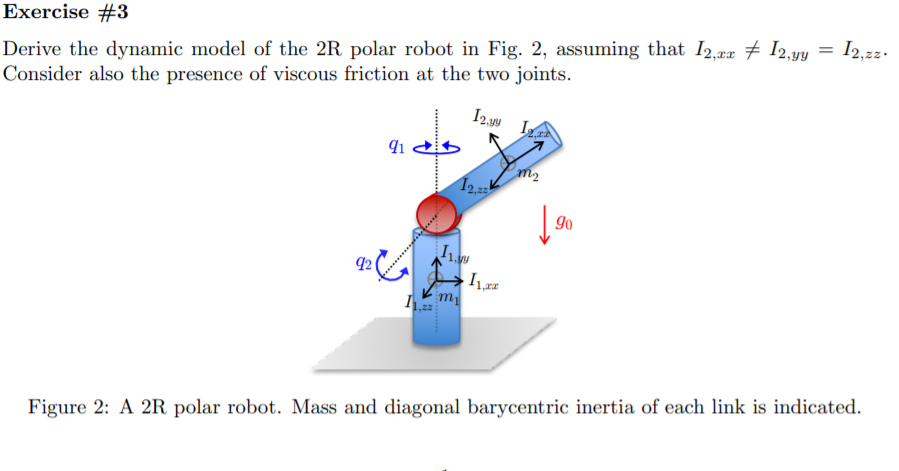

% % close all
% % % Lengths just to test
% % d1_=10;
% % d2_=10;
% % a2_=10;
% % % % De Luca's approach
% %  links = [
% %     Revolute('a', 0, 'alpha', -pi/2 ,'d', 1);
% %     Revolute('a', a2_, 'alpha',0,'d', 0);
% % %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% % %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
% %     ];
% % % 
% %  c600 = SerialLink(links);
% %  c600.teach([0 0],'view','x');
% % % c600.plot([0  pi/2 20 0],'view','x')
% % clear

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';

% R2Robot=['rr';'zx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% % z.I=I;
% z.methodD=2%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
%             0       , z.l(2)  , 0   , q(2);]

% 
% %[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2_xyz(z)

% Pc
% % Trans.PPartial{1}
% vc
% simplify(collect(expand(vc(:,2)'*vc(:,2)),z.q_dot(1)^2))
% Ti(1)
% Ti(2)
% M

% [Msubs, dynamicParameters, aM] = getDynamicParameters(M,z.q,[])

% Msubs
% % 
% 
% % PC_EEShort.J
% % PC_EEShort.f

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

% [C,cac,Csubs,] = getCs(Msubs,z.q,z.q_dot)

% cac

% g_q
% U{:}

% F_v=sym('F',[2,1],'real')
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,g_q,F_v],q,[q_dot.',g0],2)
% [All, dynamicParamsReturn, a]= getDynamicParameters([M,g_q,F_v],q,[q_dot.'],2)

% 
% All

% %complete model
% M_subs_     =All(:,1:n)
% g_q_        =All(:,n+1)
% F_v_        =All(:,n+2)
% M_subs_*z.q_ddot+cac+g_q_+F_v_.*z.q_dot%=Tao

## 6

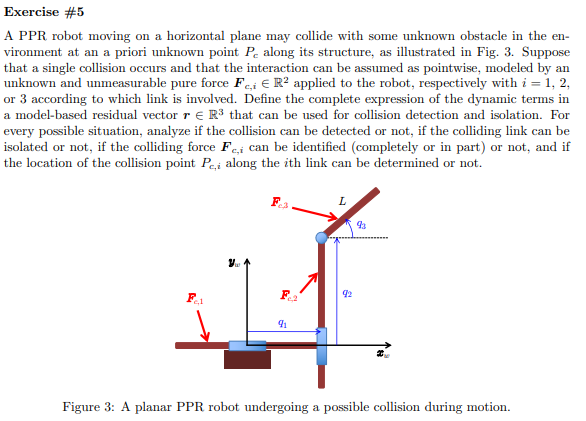

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,1];
% R2Robot=['ppr';'xyx';sigmaD]
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% % z.prismatic_CoM_method(2)=2;

% 
% 
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)

% 
% [C,cac,Csubs,S] = getCs(M,z.q,q_dot);

% Pc
% M
% S

Viscouz terms

% % % F_v=sym('F_v',[n,1],'real').*eye(n)

## gravity computation

% % isMotor=false
% % [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% % U{:}

% % g_q

## get dinamyc paramters

% % % [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
% % % [Gsubs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[g0],1)
% % % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% % [C,cac,Csubs,S1] = getCs(M,q,q_dot)
% % % u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)
% % % [usubs, dynamicParametersu, au] = getDynamicParameters(u,q,[])
% % %
% % % Msubs = All(:,1:n)
% % % gSubs = diag(All(:,n+1:2*n))
% % % FSubs = All(:,2*n+1:end)
% % [Md,Mtd,qt]  = getM_dot2(M, q, q_dot)

% % [S0,S_] = getGenericS0(q,q_dot)
% % S_(:,1)
% % S0{1}
% % % S0_=subs(S0{2},S_(:,1)',[q_dot(2),0]);
% % S0_=subs(S0{1},S_(:,2)',[-z.m(2)*z.q_dot(1)*(z.dc(2)-z.q(2)),0]);
% % S0_
% % S2=S1+S0_
% % S1
% % Md
% % simplify(Md-2*S1)
% % simplify(Md-2*S2)

% % % u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

**Collisions**

defining collisions link 1

% % %
% % % collide1=
% rho=sym('rho',[2,1],'real')
% F=sym('F_',[3,1],'real')
% F_=[0,F(2),0]'
% z.collides=[struct('F',F_ ,'joint',1,'F_pos',rho(1)),
% % z.collides=[struct('F',F_0*[cos(q(1)),sin(q(1)),0]' ,'joint',1,'F_pos',z.q(1)-rho(1)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

computing colissions

% z.prismatic_CoM_method=[2,2,1]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% % zout.g_q
% zout.S
% zout.J_c_collisions_{:}
% zout.J_c_collisions{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% zout.r
% zout.p_r
% zout.to_integrate
% % % vc_=subs(vc,q,q_)
% % % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % 

Defining collisions link 2

% %
% % collide1=
% rho=sym('rho',[2,1],'real')
% % F_0=sym('F_0','real');
% F=sym('F_',[3,1],'real')
% % F_=[0,F(2),0]'
% z.collides=[struct('F',F ,'joint',2,'F_pos',rho(2)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

Computing colissions on link 2

% z.prismatic_CoM_method=[2,2,1]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% % zout.g_q
% zout.S
% zout.J_c_collisions_{:}
% zout.J_c_collisions{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% zout.r
% zout.p_r
% zout.to_integrate
% % % vc_=subs(vc,q,q_)
% % % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % 

Defining collisions link 3

% %
% % collide1=
% rho=sym('rho',[3,1],'real')
% % F_0=sym('F_0','real');
% F=sym('F_',[3,1],'real')
% % F_=[0,F(2),0]'
% z.collides=[struct('F',F ,'joint',3,'F_pos',rho(3)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

Computing colissions on link 3

% z.prismatic_CoM_method=[2,2,1]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% % zout.g_q
% zout.S
% zout.J_c_collisions_{:}
% zout.J_c_collisions{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% zout.r
% zout.p_r
% zout.to_integrate
% % % vc_=subs(vc,q,q_)
% % % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % 
% % 